# **Global variable**

image = imread('lena.jpeg');  % Read the input image
saveNameBefore = 'lenaBefore.jpeg';  % Filename to save the grayscale image before compression
saveNameAfter = 'lenaAfter.jpeg';    % Filename to save the compressed image after processing

scaling = 20;  % Define the scaling factor for quantization

# **1.Find C8**

C8 = findDCTMatrix();  % Call function to generate the DCT matrix
inve = inv(C8);        % Calculate the inverse of the DCT matrix
transpo = C8';         % Calculate the transpose of the DCT matrix

% Check if the inverse is equal to the transpose (should be close to zero)
transpo - inve; % Output the difference for verification (should be around 10^-15)

# **2. JPEG encoding**

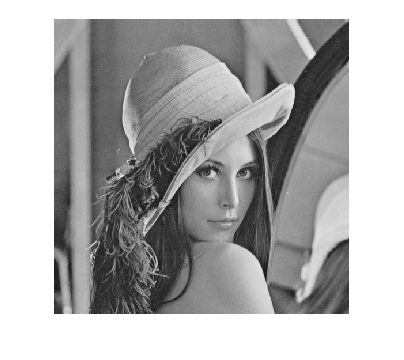

grayImage = rgb2gray(image);  % Convert the RGB image to grayscale
imwrite(grayImage, saveNameBefore);  % Save the grayscale image before compression
grayImage = pading(grayImage);  % Apply padding to the grayscale image for block processing
imshow(grayImage);  % Display the padded grayscale image

figure;  % Create a new figure window

**2.1.Block divide **

mySplit = SplitImage(grayImage);  % Call function to split the image into blocks

**2.2. DCT block **

blocksDCT = DCTBlock(mySplit, C8, 0);  % Call function to perform DCT on the image blocks

**2.3. Quantization **

load 'DCTQ';  % Load the quantization matrix from a file

JPEGRes = QuantJPEG(blocksDCT, DCTQ, scaling);  % Call function to quantize the DCT blocks

# **3. JPEG decoding**

**3.1.Rescaling the data blocks **

rescaleIM = rescaling(JPEGRes, DCTQ, scaling);  % Call function to rescale the quantized blocks

**3.2. DCT block inverse**

blocksIDCT = DCTBlock(rescaleIM, C8, 1);  % Call function to perform the inverse DCT on the rescaled blocks

**3.3. Merging the blocks **

JPEGImage = recombinesBlocks(blocksIDCT);  % Call function to recombine the blocks into a single image

# **4. Save the compressed image**

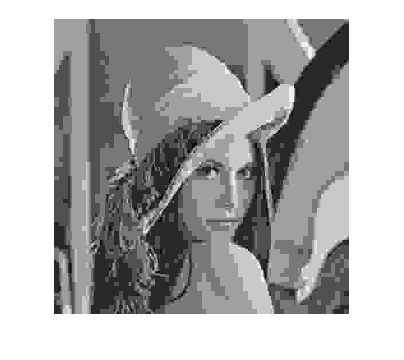

imwrite(JPEGImage, saveNameAfter);  % Save the compressed image after processing
imshow(JPEGImage);  % Display the final compressed image